% === 데이터 불러오기 ===
t_q = out.q.time;
q = out.q.signals.values;

t_e = out.error.time;
e = out.error.signals.values;

% === 차원 축소
if ndims(q) == 3
    q = squeeze(q);
end

if ndims(e) == 3
    e = squeeze(e);
end

% === Transpose 에러 값 (행-열 반전)
if size(e, 1) == 6 && size(e, 2) > 10
    e = e.';  % [6 x N] → [N x 6] 변환
end

% === 시간 길이 맞추기
min_len = min([length(t_q), size(q,1), length(t_e), size(e,1)]);
t_q = t_q(1:min_len);
q = q(1:min_len, :);
t_e = t_e(1:min_len);
e = e(1:min_len, :);

% === 그래프 그리기
figure;

% 1. Joint Positions
subplot(2,1,1);
hold on;
for i = 1:size(q, 2)
    plot(t_q, q(:, i), 'LineWidth', 1.5);
end
title('Joint Positions');
xlabel('Time (s)');
ylabel('Position (rad)');
legend('Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5', 'Joint 6');

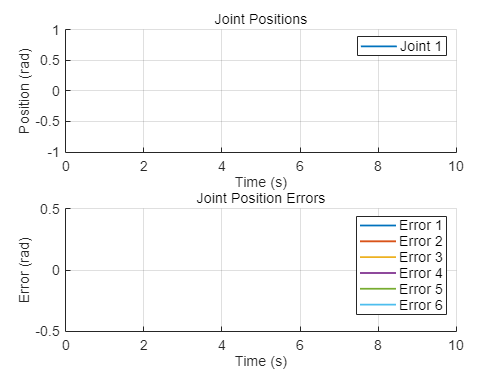

xlim([0 10]);
grid on;
hold off;

% 2. Joint Errors
subplot(2,1,2);
hold on;
for i = 1:size(e, 2)
    plot(t_e, e(:, i),  'LineWidth', 1.5);
end
title('Joint Position Errors');
xlabel('Time (s)');
ylabel('Error (rad)');
legend('Error 1', 'Error 2', 'Error 3', 'Error 4', 'Error 5', 'Error 6');
xlim([0 10]);
ylim([-0.5 0.5]);

grid on;
hold off;

% === 전체 폰트 크기 통일
set(findall(gcf,'-property','FontSize'),'FontSize',12);